## **Method of False Position**:

An algorithm for finding roots which retains that prior estimate for which the function value has opposite sign from the function value at the current best estimate of the root. In this way, the method of false position keeps the root bracketed

                              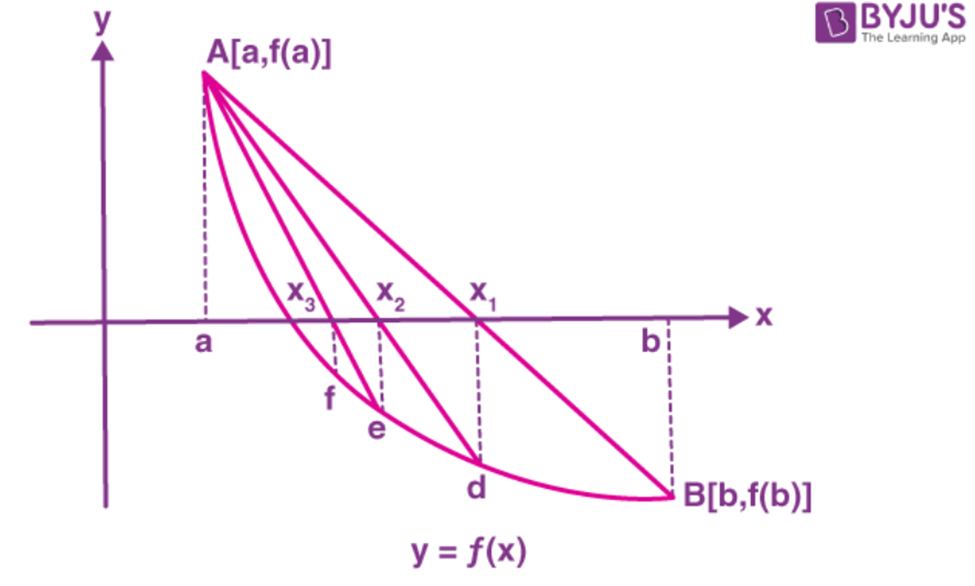

Consider an equation f(x) = 0, which contains only one variable, i.e., x.

To find the real root of the equation f(x) = 0, we consider a sufficiently small interval (a, b) where a < b such that f(a) and f(b) will have opposite signs. According to the intermediate value theorem, this implies a root lies between a and b.

Also, the curve y = f(x) will meet the x-axis at a certain point between A [a, f(a)] and B [b, f(b)].

Now, the equation of the chord joining A [a, f(a)] and B [b, f(b)] is given by:

Let y = 0 be the point of intersection of the chord equation (given above) with the x-axis. Then,

This can be simplified as: 

Thus, the first approximation is x1 = [a f(b) – b f(a)]/ [f(b) – f(a)]

Also, x1 is the root of f(x) if f(x1) = 0.

If f(x1) ≠ 0 and if f(x1) and f(a) have opposite signs, then we can write the second approximation as:

x2 = [af(x1) – x1f(a)]/ [f(x1) – f(a)]

Similarly, we can estimate x3, x4, x5, and so on.

Thus the algorithm is- 

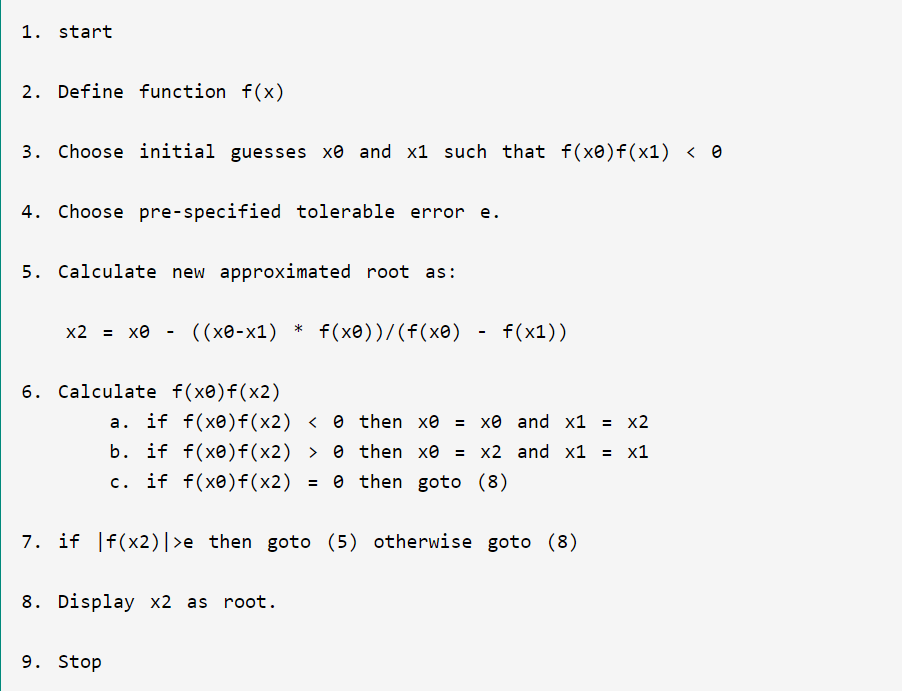

load data_falsi.mat
false_position(f,x0,x1,tol,itr)

 Iteration 1 = 0.4299 
 Iteration 2 = 0.3964 
 Iteration 3 = 0.3815 
 Iteration 4 = 0.3752 
 Iteration 5 = 0.3725 
 Iteration 6 = 0.3714 
 Iteration 7 = 0.3709 
 Iteration 8 = 0.3707 
 Iteration 9 = 0.3706 
 Iteration 10 = 0.3706 
 Iteration 11 = 0.3706 
 Iteration 12 = 0.3706 
 Iteration 13 = 0.3706 
 Iteration 14 = 0.3706 
Solution is 0.370558 at iteration 15 

%Regula falsi method
%put input values -
%Enter the function     @(x) 4*exp(-x)*sin(x)-1
%Enter x0=  0
%Enter x1=  .5
%Enter tolerance=  .0001
%Enter number of iteration=  100

function false_position(f,x0,x1,tol,itr)
%f = input('Enter the function');
%x0=input('Enter x0=');
%x1=input('Enter x1=');
%tol=input('Enter tolerance=');
%itr=input('Enter number of iteration=');

if f(x0)*f(x1)<0
p=0;
for i=1:itr
    x2=(x0*f(x1)-x1*f(x0))/(f(x1)-f(x0));
    if abs(x2-x1) < tol
        p=1;
        k=i;
        break;
    else
        if f(x0)*f(x2)<0
           x1=x2;
        else
            x0=x2;
        end
    end
    fprintf(' Iteration %d = %.4f \n',i,x2)
end


if p==1
    fprintf('Solution is %f at iteration %i ',x2,k)
else
    fprintf('No convergent solution exist in the given number iteration ')
end
else 
    disp('No root in given brackets')
end
end